clear;
clc;

%file= 'measurement/OpenB_movs/mainpos.edf';
file= 'measurement/test/test_close.edf';

file = 'measurement/test/test_close.edf'

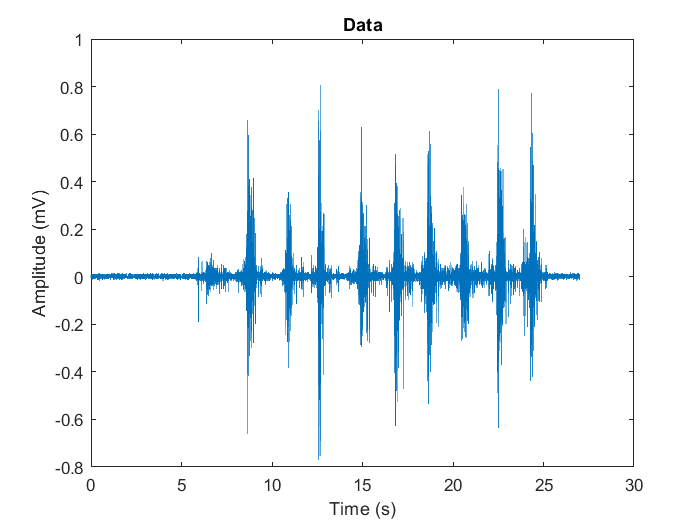

info= edfinfo(file);
signal= edfread(file, 'SelectedSignals','EMGBITREV');
fs = info.NumSamples/seconds(info.DataRecordDuration);
data_carray= table2array(signal);
data= vertcat(data_carray{:});

t= 0: 1/fs: (length(data)-1)*(1/fs);
L= length(data);
f= (0:L/2)*(fs/L);

figure()
plot(t,data);
title('Data');
ylabel('Amplitude (mV)');
xlabel('Time (s)')

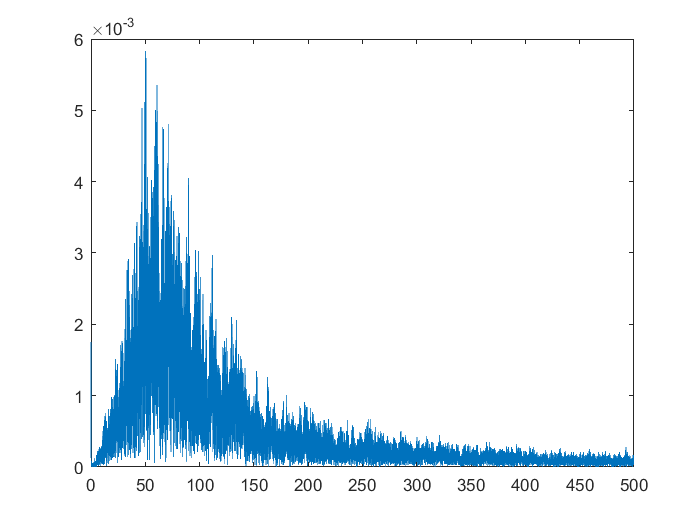


y= fft(data);
y= abs(y/L);
y= y(1: L/2+1);
plot(f, 2*y);

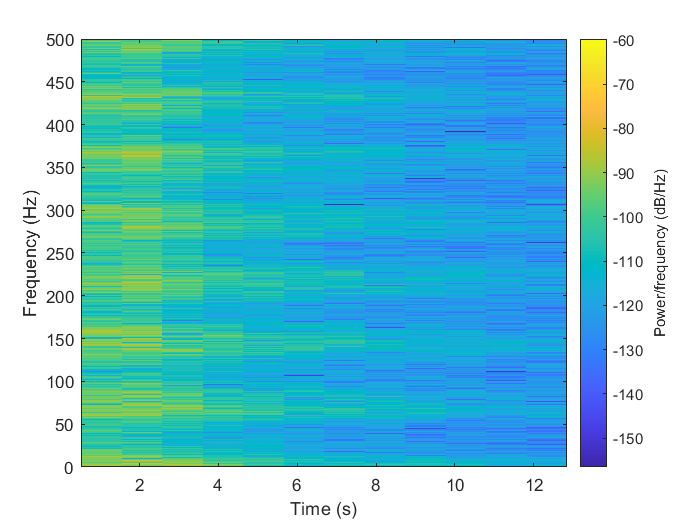

spectrogram(abs(y), 2048, 1020, 2048, fs, 'yaxis');

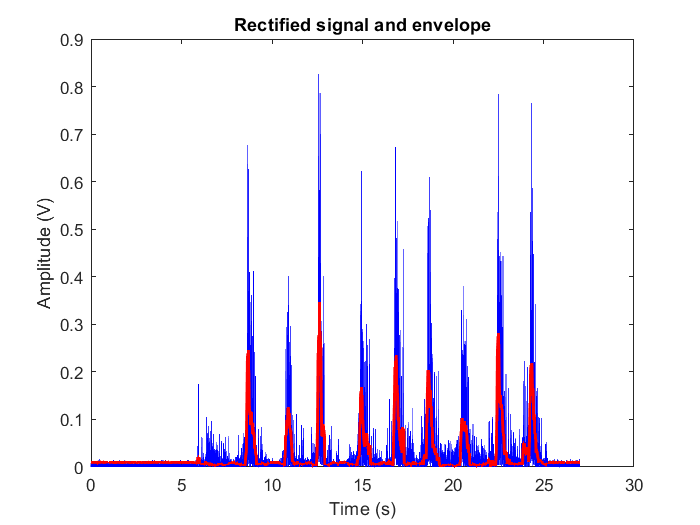


fnyq= fs/2;
fh= 20;
fl= 450;

[b, a]= butter(4, [fh, fl]/fnyq, "bandpass");

data= filtfilt(b, a, data);
rec_signal= abs(data);    % matlab doesn't know its mV
[YUPPER, YLOWER]= envelope(rec_signal, fs/10, 'rms');
YUPPER= YUPPER- min(YUPPER);
p= plot(t, rec_signal, 'b', t, YUPPER, 'r');
p(2).LineWidth= 1.5;
title('Rectified signal and envelope');
xlabel('Time (s)');
ylabel('Amplitude (V)')

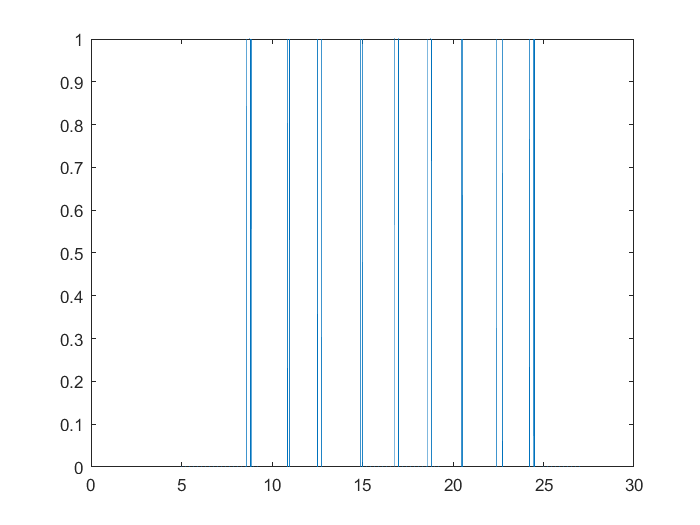


%decision
decision= YUPPER>=0.10;
plot(t, decision);


% noise filtering, 50Hz peak
%disp("Filtered noise.")


%filtrar, passsa baixo


%threshoulding and amplification
% we want a maximum of 5V, (for now) max is 1mV
%data= data*5; % in arduino thats not the value

